# Bandpass filter design - 180497C

## Filter Specifications I

clc; clear; close all;

%Index number  = 180497C
A = 4;
B = 9;
C = 7;

%Maximum passband ripple in dB
Ap = 0.03 + (0.01*A);
%Minimum stopband attenuation in dB
Aa = 45 + B;
%Lower passband edge in rad/s
Omega_p1 = (C*100) + 300;
%Upper passband edge in rad/s
Omega_p2 = (C*100) + 700;
%Lower stopband edge in rad/s
Omega_a1 = (C*100) + 150;
%Upper stopband edge in rad/s
Omega_a2 = (C*100) + 800;
%Sampling frequency in rad/s
Omega_s = 2*((C*100) + 1200);
%Sampling period
Ts = 2*pi/Omega_s;

## Filter Specifications II

%Transition width in rad/s
Bt = min((Omega_p1-Omega_a1),(Omega_a2-Omega_p2));
%Lower cutoff frequency in rad/s
Omega_c1 = Omega_p1 - Bt/2;
%Upper cutoff frequency in rad/s
Omega_c2 = Omega_p2 + Bt/2;

## Determining Kaiser Window Parameters

%Calculating delta_p
dp = (10^(0.05*Ap)-1)/((10^(0.05*Ap)+1));
%Calculating delta_a
da = 10^(-0.05*Aa);
%Selecting the minimum delta
delta = min(dp,da);

%Actual passband ripple in dB
Ap = 20*log10((1+delta)/(1-delta));
%Actual stopband attenuation in dB
Aa = -20*log10(delta);

%Choosing alpha
if Aa <= 21
    alpha = 0;
elseif Aa > 21 && Aa <= 50
    alpha = 0.5842*(Aa-21)^0.4 + 0.07886*(Aa-21);
else
    alpha = 0.1102*(Aa-8.7);
end

%Choosing D
if Aa <= 21
    D = 0.9222;
else
    D = (Aa - 7.95)/14.36;
end

%Choosing the length of the filter
N = ceil((Omega_s*D/Bt)+1);
if rem(N,2) == 0
    N = N+1;
end

%Filter duration
range = 0:1:N-1;
M = (N-1)/2;
n = 0:1:M;

%Calculating beta
beta = alpha*sqrt(1-((2*n)/(N-1)).^2);

## Generating the Bessel Functions

%No.of iterations
Iter =  100;

%Generating I(alpha)
I_alpha = 1;
for i = 1:Iter
    I_alpha = I_alpha + ((1/factorial(i))*((alpha/2)^i))^2;
end

%Generating I(beta)
I_beta = 1;
for i = 1:Iter
    I_beta = I_beta + ((1/factorial(i))*((beta/2).^i)).^2;
end

## Kaiser Window

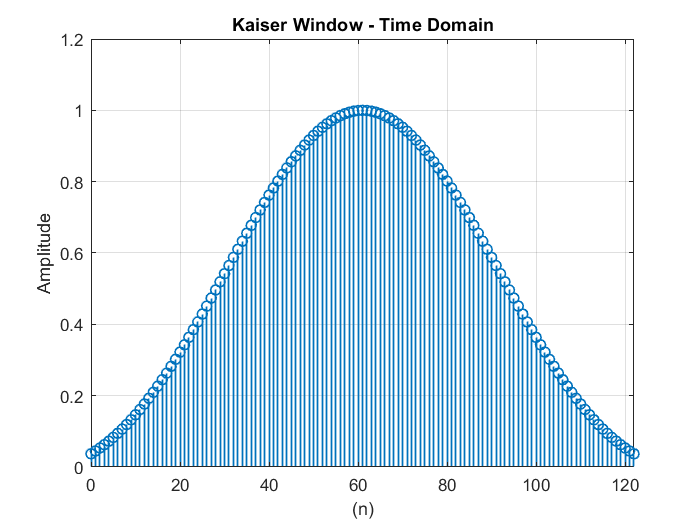

%defining the kaiser window
kaiser_win = I_beta/I_alpha;
kaiser_win = [fliplr(kaiser_win(2:end)) kaiser_win];
figure(1)
stem(range,kaiser_win,'Linewidth',1)
xlabel('(n)')
ylabel('Amplitude')
axis([0 N-1 0 1.2])
grid on
title('Kaiser Window - Time Domain')

## Filter Using a Rectangular Window

This is the idealized impulse response truncated using a rectangular window.

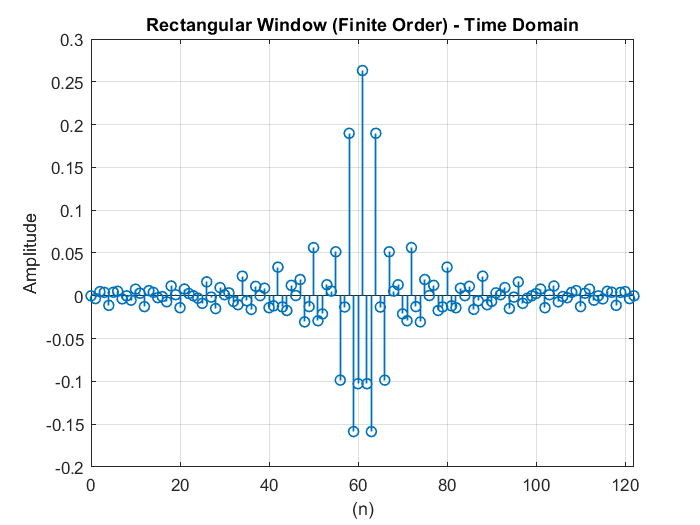

%assuming an idealized frequency response
hnT = zeros(1,N);
for i = 0:M
    if i == 0
        hnT(i+M+1) = (2/Omega_s)*(Omega_c2 - Omega_c1);
    else
        hnT(i+M+1) = (1/(i*pi))*(sin(Omega_c2*i*Ts) - sin(Omega_c1*i*Ts));
    end
end

hnT(1:M) = fliplr(hnT(M+2:end));

%plotting the idealized impulse response of finite order - time domain
stem(range, hnT,'Linewidth',1)
axis([0 122 -0.2 0.3])
grid on
xlabel('(n)')
ylabel('Amplitude')
title('Rectangular Window (Finite Order) - Time Domain')

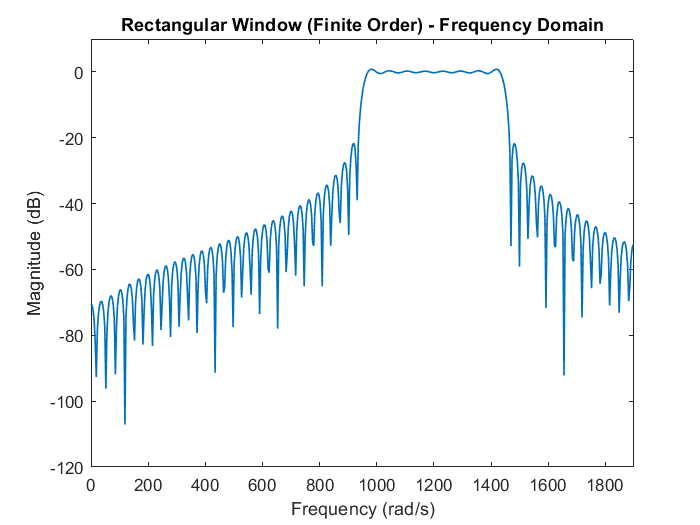


%Plotting the idealized impulse response of finite order - frequnecy domain
[h_ideal,w_ideal] = freqz(hnT);
Omega_ideal = w_ideal/Ts;
h_ideal = 20*log10(abs(h_ideal));
plot(Omega_ideal,h_ideal,'Linewidth',1)
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Rectangular Window (Finite Order) - Frequency Domain')
axis([0 Omega_s/2 -120 10])

## Causal Impulse Response

This section plots the causal impulse response for a BPF designed using a Kaiser window

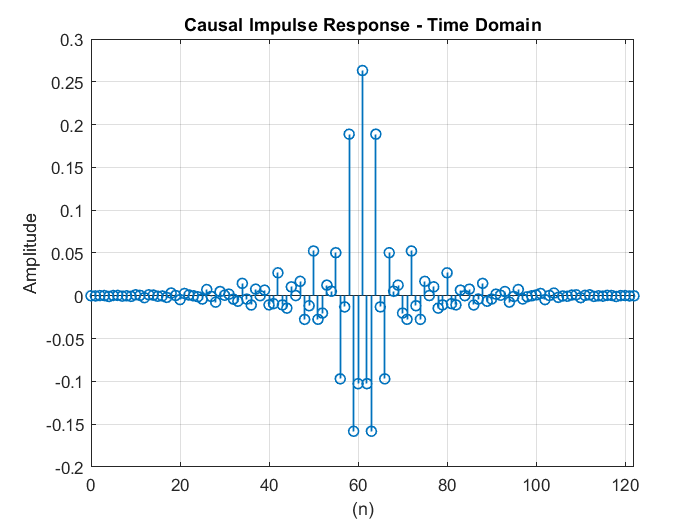

%Defining the filter using the Kaiser window
filter = kaiser_win.*hnT;

%Plotting the causal impulse response of the filter - time domain
stem(range, filter,'Linewidth',1)
axis([0 N-1 -0.2 0.3])
grid on
xlabel('(n)')
ylabel('Amplitude')
title('Causal Impulse Response - Time Domain')

## Magnitude Response of the Filter (0 to $\frac{\Omega_s }{2}$ (rad/s))

In this section, we are trying to plot the magnitude response of the digital filter obtained, for the frequency range 0 to $\frac{\Omega_s }{2}$ (rad/s).

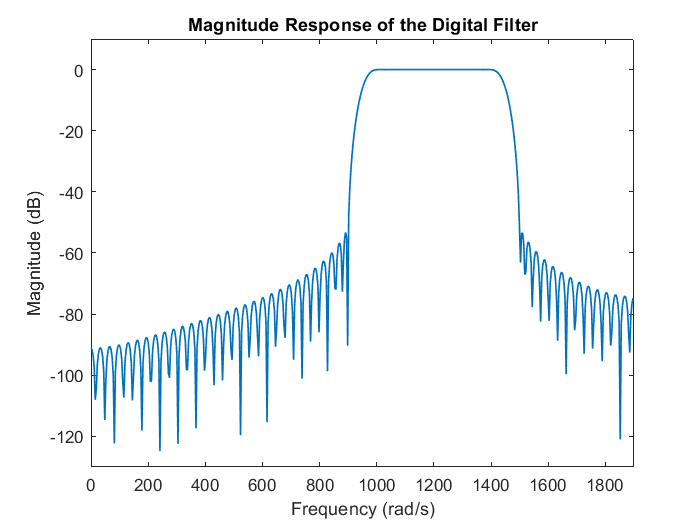

%Plotting the magnitude of the filter
[h,w] = freqz(filter);
Omega = w/Ts;
h = 20*log10(abs(h));
plot(Omega,h,'Linewidth',1)
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Magnitude Response of the Digital Filter')
axis([0 Omega_s/2 -130 10])

## Magnitude Response of the Filter in the Passband

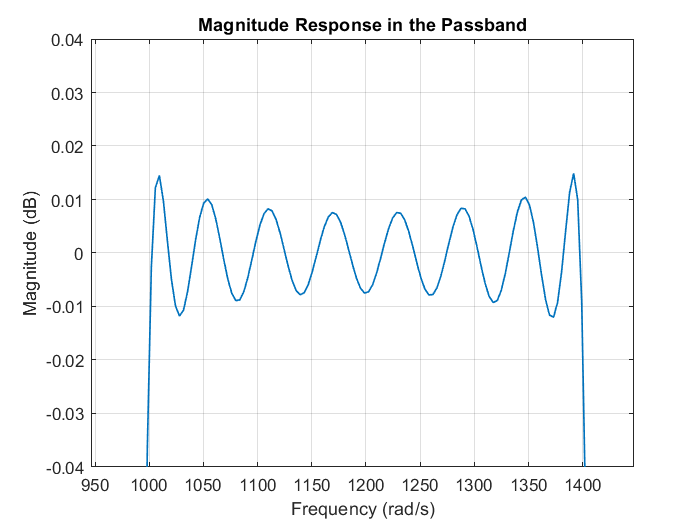

lower_margin = round((length(Omega)/(Omega_s/2))*Omega_c1);
upper_margin = round((length(Omega)/(Omega_s/2))*Omega_c2);
%Passband frequencies
passband = Omega(lower_margin:upper_margin);
mag_passband = h(lower_margin:upper_margin);
plot(passband,mag_passband,'Linewidth',1)
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Magnitude Response in the Passband')
axis([-Inf Inf -0.04 0.04])
grid on

## Generating the Input Signal

%Finding the component frequencies
Omega_1 = (0 + Omega_a1)/2;
Omega_2 = (Omega_p1 + Omega_p2)/2;
Omega_3 = (Omega_a2 + Omega_s/2)/2;

samples = 500;
%to generate the discrete signal
n1 = 0:1:samples;
%to envelope the the discrete signal using a CT signal
n2 = 0:0.0001:samples;

%input DT signal
xnT = sin(Omega_1.*n1.*Ts) + sin(Omega_2.*n1.*Ts) + sin(Omega_3.*n1.*Ts);
%CT signal (envelope)
envelope = sin(Omega_1.*n2.*Ts) + sin(Omega_2.*n2.*Ts) + sin(Omega_3.*n2.*Ts);

## Displaying the Input Signal

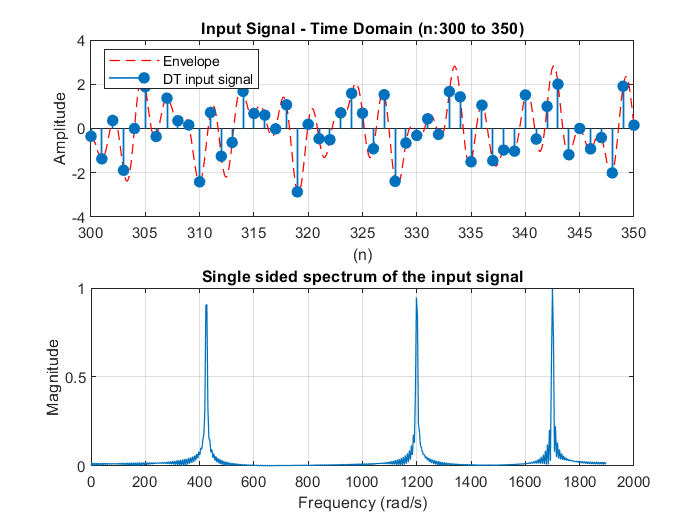

%plotting a sample of the input signal in time domain
subplot(2,1,1)
plot(n2,envelope,'r--','LineWidth',0.75)
hold on
stem(n1, xnT,'filled','LineWidth',1)
xlabel('(n)')
ylabel('Amplitude')
title('Input Signal - Time Domain (n:300 to 350)')
xlim([300,350])
grid on
legend('Envelope','DT input signal','Location','best')
hold off

%Calculating FFT of the input signal
numpoints = 2^(nextpow2(numel(xnT)+numel(filter)));
x_fft = fft(xnT,numpoints);
magnitudes = abs(x_fft/numel(xnT));
magnitudes = magnitudes(:,1:numpoints/2+1);
magnitudes(:,2:end-1) = 2*magnitudes(:,2:end-1);
freq = 0:(Omega_s/numpoints):(Omega_s/2)-Omega_s/numpoints;

%plotting the input signal in the frequency domain
subplot(2,1,2)
plot(freq,magnitudes(1:numpoints/2),'LineWidth',0.75)
xlabel('Frequency (rad/s)')
ylabel('Magnitude')
title('Single sided spectrum of the input signal')
grid on

## Filtering the Input Signal

In this section, we will filter the input signal using the designed bandpass filter. First, we will consider the frequency domain multiplication of the input and the filter. Then, we will compensate for the shifting delay 

filter_fft = fft(filter,numpoints);
y_fft = x_fft.*filter_fft;
ynT = ifft(y_fft,numpoints);
ynT = ynT(floor(N/2)+1:numel(ynT)-floor(N/2));


The ideal output would be $\mathrm{sin}\left(1200\mathrm{nT}\right)$

%constructing an envelope similar to the ideal output
y_ideal = sin(Omega_2.*n2.*Ts);

## Displaying the Output Signal

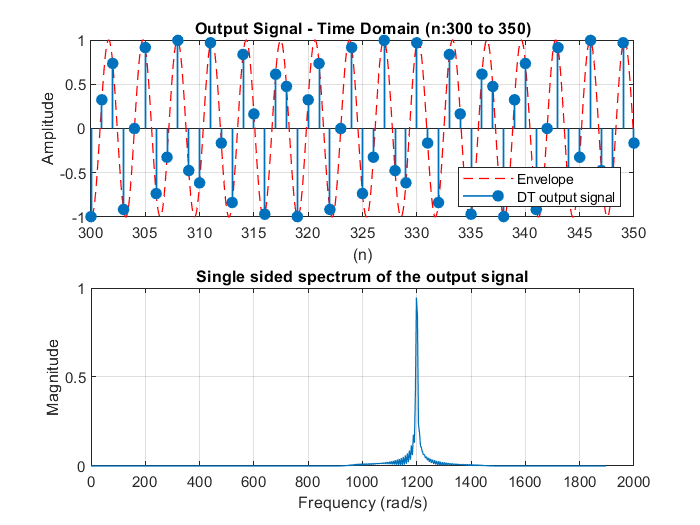

%plotting a sample of the output signal in time domain
subplot(2,1,1)
plot(n2,y_ideal,'r--','LineWidth',0.75)
hold on
stem(n1, ynT(1:samples+1),'filled','LineWidth',1)
xlabel('(n)')
ylabel('Amplitude')
title('Output Signal - Time Domain (n:300 to 350)')
xlim([300,350])
grid on
legend('Envelope','DT output signal','Location','southeast')
hold off

%FFT parameters of the output signal
magnitudes_out = abs(y_fft/(samples+1));
magnitudes_out = magnitudes_out(:,1:numpoints/2+1);
magnitudes_out(:,2:end-1) = 2*magnitudes_out(:,2:end-1);
freq_out = 0:(Omega_s/numpoints):(Omega_s/2)-Omega_s/numpoints;

%plotting the output signal in the frequency domain
subplot(2,1,2)
plot(freq_out,magnitudes_out(1:numpoints/2),'LineWidth',0.75)
xlabel('Frequency (rad/s)')
ylabel('Magnitude')
title('Single sided spectrum of the output signal')
grid on

## Comparing the Output with the Ideal Output

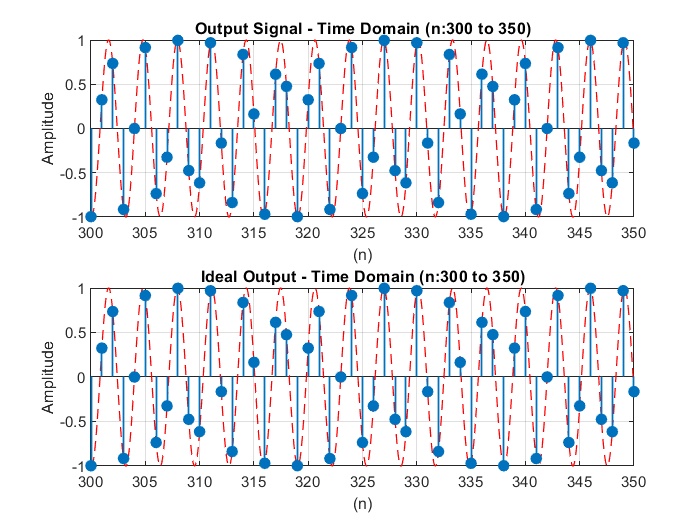

%ideal output
yT = sin(Omega_2.*n1.*Ts);
y_ideal_fft = fft(yT,numpoints);
%FFT parameters of the ideal output signal
magnitudes_ideal = abs(y_ideal_fft/(samples+1));
magnitudes_ideal = magnitudes_ideal(:,1:numpoints/2+1);
magnitudes_ideal(:,2:end-1) = 2*magnitudes_ideal(:,2:end-1);
freq_ideal = 0:(Omega_s/numpoints):(Omega_s/2)-Omega_s/numpoints;

figure(1)
%comparing the results with the ideal output - time domain
subplot(2,1,1)
plot(n2,y_ideal,'r--','LineWidth',0.75)
hold on
stem(n1, ynT(1:samples+1),'filled','LineWidth',1)
xlabel('(n)')
ylabel('Amplitude')
title('Output Signal - Time Domain (n:300 to 350)')
xlim([300,350])
grid on
hold off

subplot(2,1,2)
plot(n2,y_ideal,'r--','LineWidth',0.75)
hold on
stem(n1, yT,'filled','LineWidth',1)
xlabel('(n)')
ylabel('Amplitude')
title('Ideal Output - Time Domain (n:300 to 350)')
xlim([300,350])
grid on
hold off

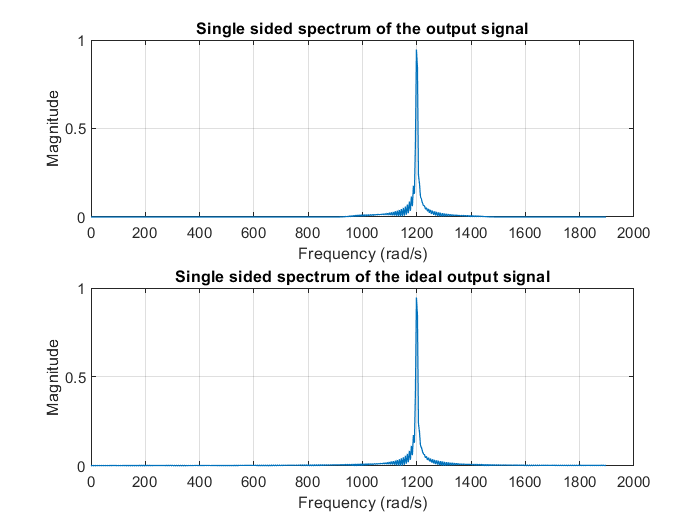


%comparing the results with the ideal output- frequency domain
figure(2)
subplot(2,1,1)
plot(freq_out,magnitudes_out(1:numpoints/2),'LineWidth',0.75)
xlabel('Frequency (rad/s)')
ylabel('Magnitude')
title('Single sided spectrum of the output signal')
grid on

subplot(2,1,2)
plot(freq_ideal,magnitudes_ideal(1:numpoints/2),'LineWidth',0.75)
xlabel('Frequency (rad/s)')
ylabel('Magnitude')
title('Single sided spectrum of the ideal output signal')
grid on